# Task Description

Use ESP to solve the double pole balancing task using all six inputs and using only three inputs (excluding the velocity information).

## Clear table

clear;
addpath('simulator');

## Initialize parameters for run with six inputs

parameters.topology = [6,2,1];
evaluationFunction = 'evaluate6Inputs';
% I implemented two ways of combining nodes to networks. The first randomly
% picks one individual from each subgroup.
% The second makes sure that each individual will be pickes as often as any
% other node.
% For this task I chose to use option nr 1 because I could not see any
% differences in the performances and this seemed to be the way that was
% used in the original ESP.
parameters.permutationOption = 1;
% I implemented two ways of applying elitism. Option 1 is keeping those
% nodes that participated in the best network.
% Option 2 is keeping those nodes with the best overall fitness.
% After performing several exhaustive tests I decided to go with option
% two.
parameters.elitismOption = 2;
parameters.maximumGenerations = 2500;
parameters.targetFitness = 1000;

## Description of Algorithm

`In my implementation of ESP each individual is represented by its`

`incoming connections. That means that for the first experiment (6,2,1)`

`it uses three subgroups only, because Bias and Input neurons do not`

`have any inputs in ESP.`

`For the selection of parents I use tournament selection with default`

`selective pressure of 2.`

`For Recombination I use randomly choose weights from one of the two`

`parents.`

`For mutation I add a normally distributed value of range 2.5 with a `

`certain likelyhood to a single weight .`

`The fitness of each node is computed by commulating the fitnesses of`

`each network the node participated in and averaging this value over the`

`number of trials.`

## Experiment 1

r(1) = doEsp(evaluationFunction, parameters);

Starting parallel pool (parpool) using the 'local' profile ... connected to 2 workers.



parameters.topology = [3,2,1];
evaluationFunction = 'evaluate3Inputs';

## Experiment 2

r(2) = doEsp(evaluationFunction, parameters);

## Visualization

Mean and best node fitness

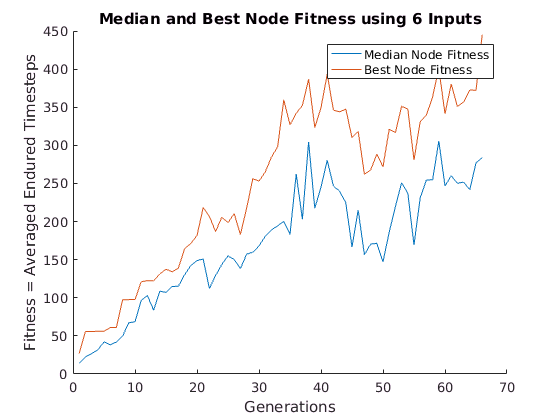

figure(1); clf; hold on;
plot(mean(r(1).medianNodeFitness,1));
plot(max(r(1).bestNodeFitness,[],1));
xlabel('Generations');
ylabel('Fitness = Averaged Endured Timesteps');
title('Median and Best Node Fitness using 6 Inputs');
legend('Median Node Fitness','Best Node Fitness');

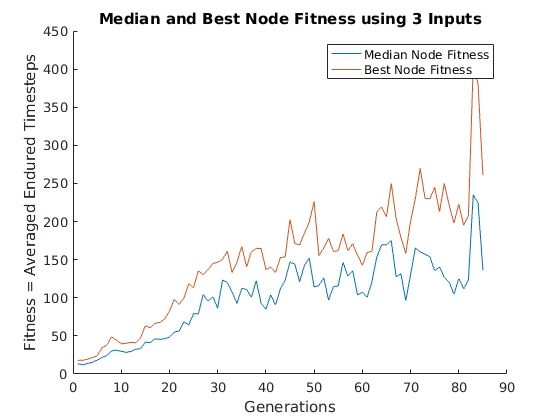

grid on;

figure(2); clf; hold on;
plot(mean(r(2).medianNodeFitness,1));
plot(max(r(2).bestNodeFitness,[],1));
xlabel('Generations');
ylabel('Fitness = Averaged Endured Timesteps');
title('Median and Best Node Fitness using 3 Inputs');
legend('Median Node Fitness','Best Node Fitness');

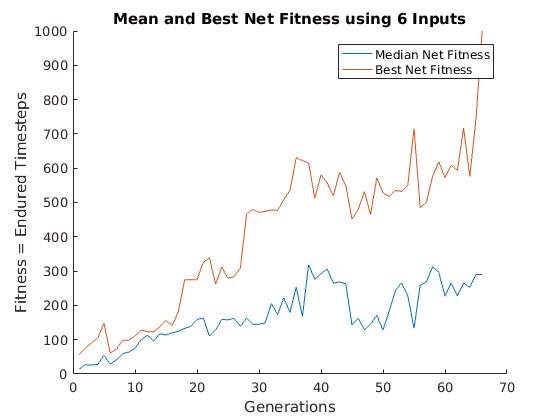

grid on;

% Mean and best network fitness
figure(3); clf; hold on;
plot(r(1).medianNetFitness);
plot(r(1).bestNetFitness);
xlabel('Generations');
ylabel('Fitness = Endured Timesteps');
title('Mean and Best Net Fitness using 6 Inputs');
legend('Median Net Fitness','Best Net Fitness');

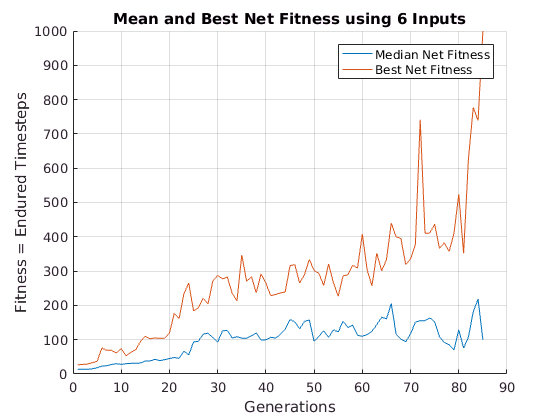

grid on;

figure(4); clf; hold on;
plot(r(2).medianNetFitness);
plot(r(2).bestNetFitness);
xlabel('Generations');
ylabel('Fitness = Endured Timesteps');
title('Mean and Best Net Fitness using 6 Inputs');
legend('Median Net Fitness','Best Net Fitness');
grid on;


% Best networks
display('Best Network for 6 Inputs');

Best Network for 6 Inputs


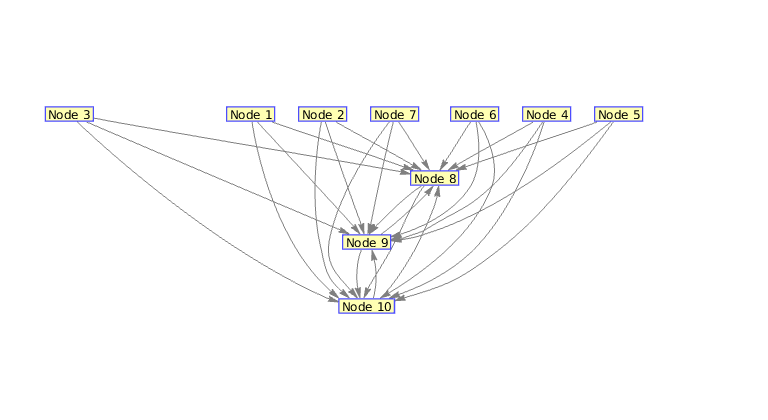

wMat = r(1).bestNetwork;
nMissingColumns = size(wMat,1) - size(wMat,2);
wMat = [zeros(size(wMat,1),nMissingColumns) wMat];
view(biograph(wMat));


display('Best Network using 3 Inputs');

Best Network using 3 Inputs


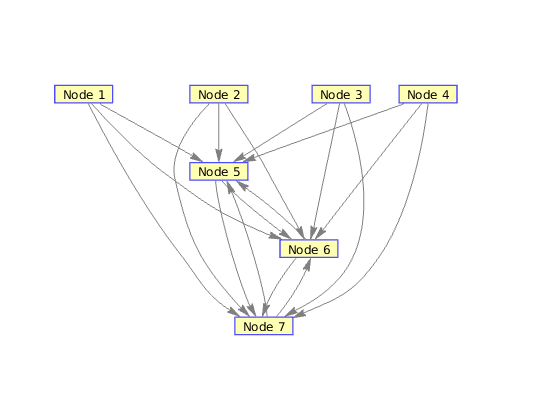

wMat = r(2).bestNetwork;
nMissingColumns = size(wMat,1) - size(wMat,2);
wMat = [zeros(size(wMat,1),nMissingColumns) wMat];
view(biograph(wMat));